# Example: Interface Parameters

When the `.calculate` method of `ElasticMatrix` is used the stresses and displacements at every interface of the multi-layered medium are calculated. These can be plotted using the `.plotInterfaceParameters `method.

## Initialize an `ElasticMatrix` Object

This example will use a three layered Medium.

% Initialize Medium object:
my_medium = Medium('PVDF', Inf, 'glass', 0.001, 'aluminium', Inf);

% Initialize ElasticMatrix object:
my_model = ElasticMatrix(my_medium);

## Setting Calculation Parameters

% Set a range of angles:
my_model.setAngle(linspace(0, 89, 100));        % [degrees]

% Set an arbitrary frequency:
my_model.setFrequency(1e6);                     % [Hz]

## Calculating and Plotting Interface Parameters

A new figure will be plotted for every interface.

% Run the model: 
my_model.calculate;

... calculating matrix method ... 
... frequency-angle calculation ...
... finished calculating matrix method ... 


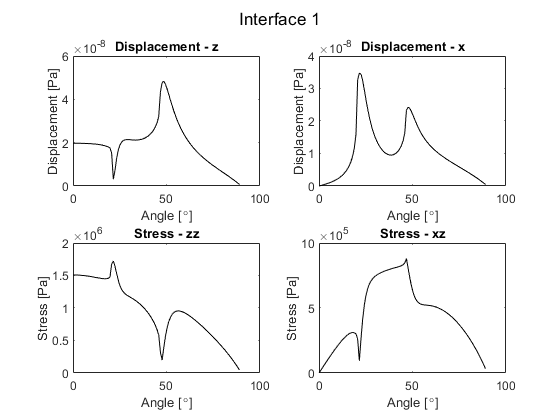

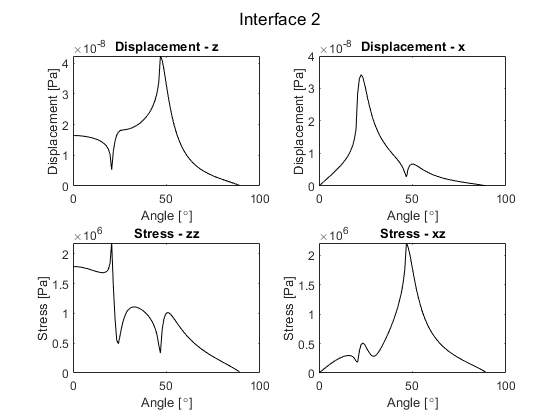

% Plot the interface parameters:
my_model.plotInterfaceParameters;